clc
clear 


#### Señales de muestras con tumor

Canal 2 

Señales 1,6,11,16

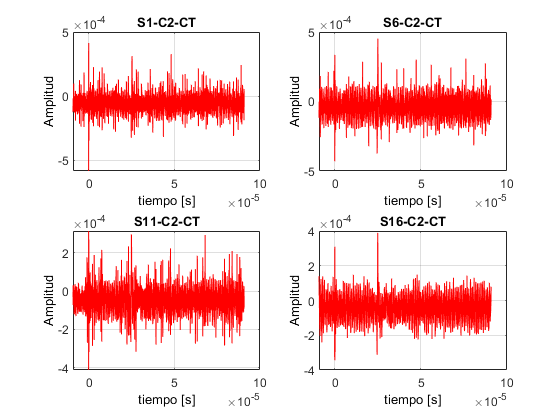

ev1=importfile("5_Ch4.csv");
a1='tiempo [s]';
a2='Amplitud';
figure(1)
subplot(2,2,1)
plot(ev1.f1,ev1.f2,'r')
xlabel(a1,'color','k')
ylabel(a2,'color','k')
grid on
title('S1-C2-CT')
%hold on
ev2=importfile("10_Ch4.csv");
subplot(2,2,2)
plot(ev2.f1,ev2.f2,'r')
xlabel(a1,'color','k')
ylabel(a2,'color','k')
grid on
title('S6-C2-CT')
%hold on
ev3=importfile("15_Ch4.csv");
subplot(2,2,3)
plot(ev3.f1,ev3.f2,'r')
xlabel(a1,'color','k')
ylabel(a2,'color','k')
grid on
title('S11-C2-CT')
%hold on
ev4=importfile("20_Ch4.csv");
subplot(2,2,4)
plot(ev4.f1,ev4.f2,'r')
xlabel(a1,'color','k')
ylabel(a2,'color','k')
grid on
title('S16-C2-CT')
hold off

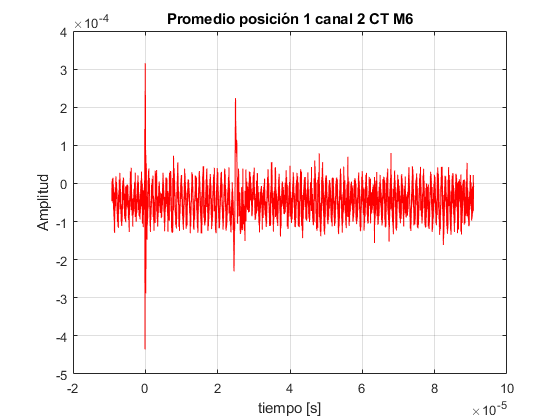

%close all
figure(2)
et1=(ev1.f2+ev2.f2+ev3.f2+ev4.f2)/4;
plot(ev1.f1,et1,'r')
grid on
title('Promedio posición 1 canal 2 CT M6')
ylabel('Amplitud');
xlabel('tiempo [s]');

#### Guardar señal promedio

ev1.f2=et1;
clear ev2 ev3 ev4
%writetable(ev1,"M6LAS3P5A14.csv");

#### Realizar tabla Señales acorde a posición 

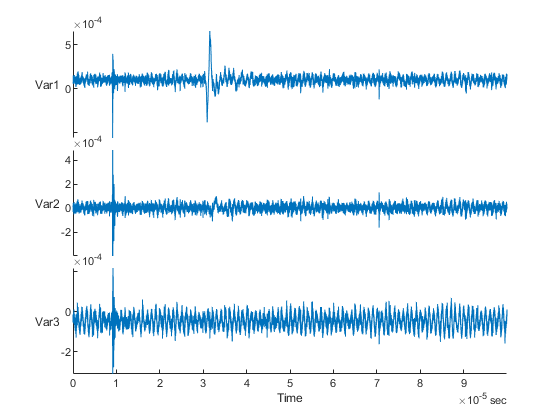

clc
clear
s1=readtable("M6LAS1P1A14.csv");
s2=readtable("M6LAS2P1A14.csv");
s3=readtable("M6LAS3P1A14.csv");
dt=seconds(2e-9);
vdv=timetable(s1.f2,s2.f2,s3.f2,'TimeStep',dt);
%writetimetable(vdv,"M6LAS13P1A14.csv");
stackedplot(vdv)

#### Leer Señal promedio

clear all
ev1=readtable("M6LAS1P1A14.csv");
et1=ev1.f2;
ev=ev1.f1;
%clear ev1

### Filtros aplicados al promedio

#### Primer filtro smotthdata

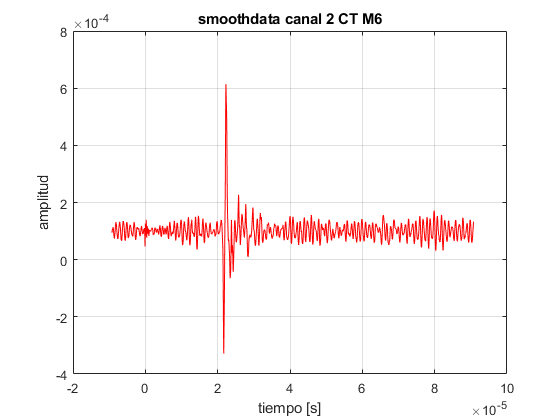


e1=smoothdata(et1,'rloess');
%e1=smoothdata(et1,'gaussian');

a1='amplitud';
a2='tiempo [s]';
figure(1)
plot(ev,e1,'r')
title('smoothdata canal 2 CT M6')
ylabel(a1);
xlabel(a2);
grid on 

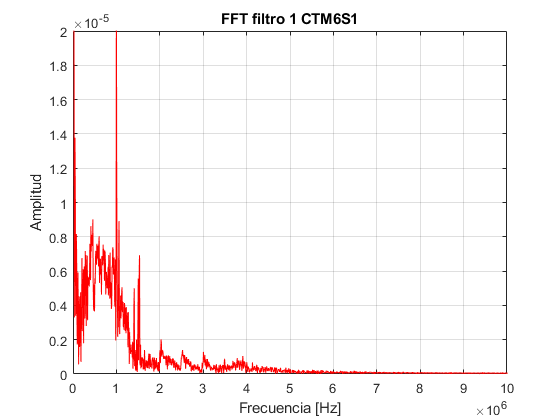

Ts=2e-9;
Fs=1/Ts;
yl=[0 2e-5];
xl=[0 10e6];

L=length(e1);
[fx,fy]=tfou(L,e1,Fs);
figure(3)
plot(fx,fy,'r')
ylim(yl)
xlim(xl)
title('FFT filtro 1 CTM6S1')
grid on
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');

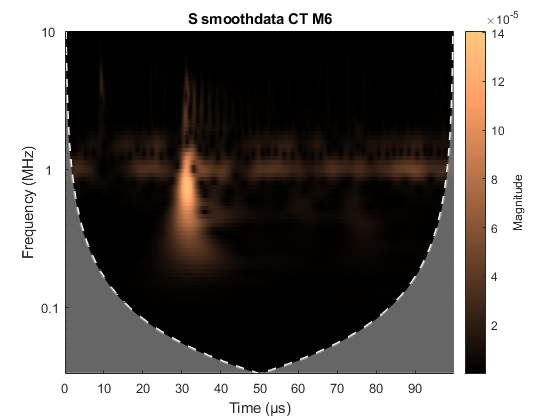


figure(5)
cwt(e1,'morse',Fs);
title('S smoothdata CT M6');
%xlim([0.0 100])
ylim([0.0 10])
colormap copper

#### Segundo filtro wdenoise

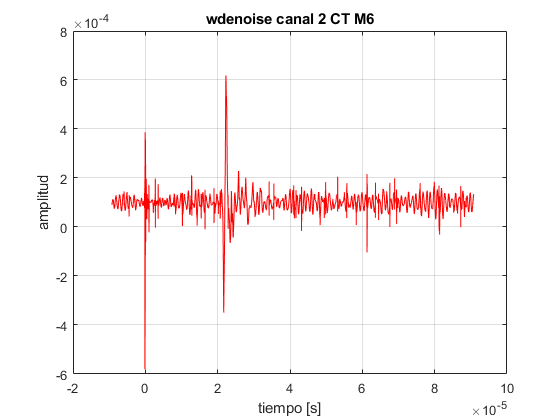


e11=wdenoise(et1,6,'NoiseEstimate','LevelDependent');
figure(2)
plot(ev,e11,'r')
title('wdenoise canal 2 CT M6')
ylabel(a1);
xlabel(a2);
grid on 

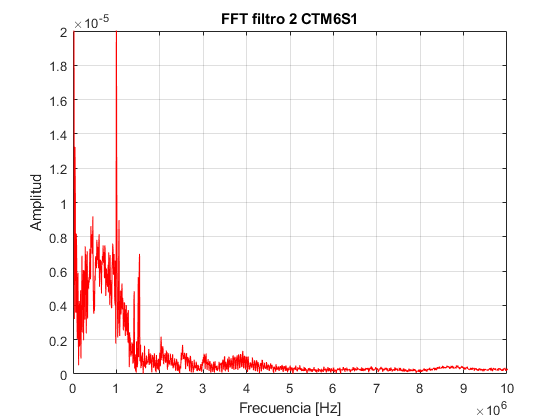


L=length(e11);
[fx,fy]=tfou(L,e11,Fs);
figure(4)
plot(fx,fy,'r')
ylim(yl)
xlim(xl)
title('FFT filtro 2 CTM6S1')
grid on
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');

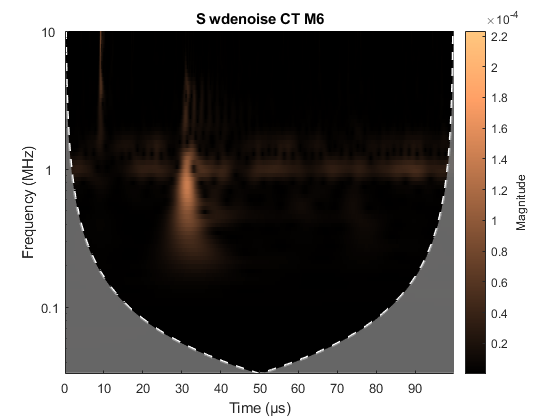


figure(4)
cwt(e11,'morse',Fs);
title('S wdenoise CT M6');
%xlim([0.0 100])
ylim([0.0 10])
colormap copper

[Denoising](https://www.mathworks.com/help/wavelet/denoising.html#:~:text=Denoise%20a%20Signal%20with%20the%20Wavelet%20Signal%20Denoiser&text=To%20reproduce%20the%20denoised%20signal,and%20edit%20a%20MATLAB%20script.)

[Smoothing and Denoising](https://www.mathworks.com/help/signal/smoothing-and-denoising.html)

[Denoise functions](https://www.mathworks.com/help/wavelet/referencelist.html?type=function&category=denoising)

#### Tercerer filtro Task Smoothdata

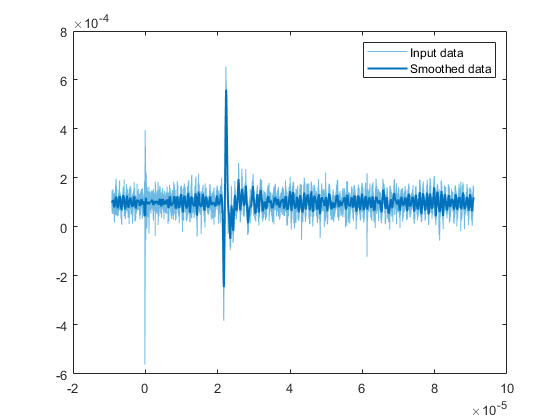

% Smooth input data
smd = smoothdata(et1,'movmean','SmoothingFactor',0.25,...
    'SamplePoints',ev);

% Display results
clf
plot(ev,et1,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on
plot(ev,smd,'Color',[0 114 189]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
legend

#### Tercer filtro Task Smoothdata

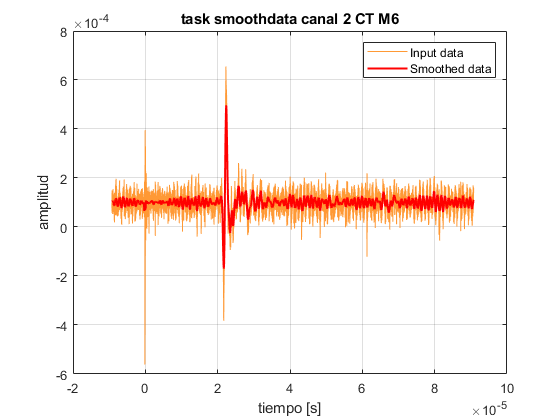


smd = smoothdata(ev1.f2,'movmean','SmoothingFactor',0.5,...
    'SamplePoints',ev1.f1);
clf
plot(ev1.f1,ev1.f2,'Color',[255 153 53]/255,'DisplayName','Input data')
hold on
plot(ev1.f1,smd,'Color',[255 0 0]/255,'LineWidth',1.5,...
    'DisplayName','Smoothed data')
hold off
title('task smoothdata canal 2 CT M6')
grid on
xlabel('tiempo [s]');
ylabel('amplitud');
legend

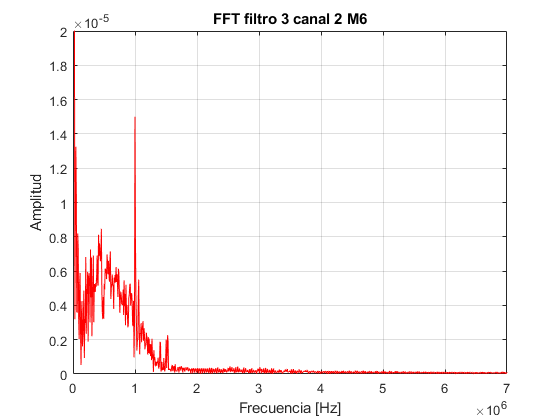


Ts=2e-9;
Fs=1/Ts;
yl=[0 2e-5];
xl=[0 7e6];
L=length(et1);
[fx,fy]=tfou(L,smd,Fs);
figure(2)
plot(fx,fy,'r')
ylim(yl)
xlim(xl)
title('FFT filtro 3 canal 2 M6')
grid on
xlabel('Frecuencia [Hz]');
ylabel('Amplitud');

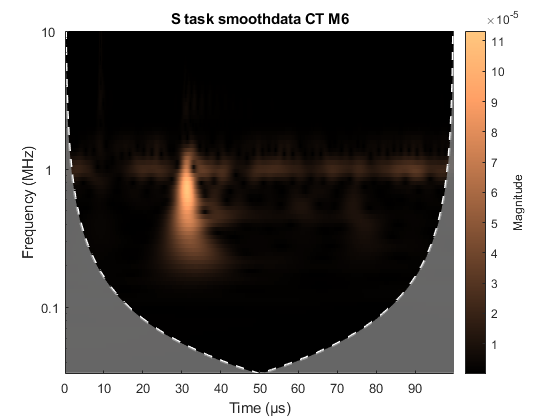


figure(7)
cwt(smd,'morse',Fs);
title('S task smoothdata CT M6');
%xlim([0.0 100])
ylim([0.0 10])
colormap copper

Lnks articulos : 

[Current and future trends](https://www.sciencedirect.com/science/article/pii/S2213597919300679) 

[Clinical imaging ](https://www.sciencedirect.com/science/article/pii/S2213597918300430)

[Human skin](https://ieeexplore.ieee.org/stamp/stamp.jsp?arnumber=7865979) 

[RF](http://www.inmodemd.it/files/PeerRev-Fractora_Aesthet-Dermatol-Basel_D-Duncan_M-Kreindel.pdf) 